syms h;
syms x1;
syms x2
f = 320.45 * (x1)^2 - 237.6*x1*x2 + 48.2*x2^2 -9.125*x1 - 9.125 * x2

$$f = \frac{6409\,{x_{1}}^{2}}{20}-\frac{1188\,x_{1}\,x_{2}}{5}-\frac{73\,x_{1}}{8}+\frac{241\,{x_{2}}^{2}}{5}-\frac{73\,x_{2}}{8}$$

x1 = 0:0.01:3

x1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


x2 = 0:0.01:3

x2 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f_plot = 320.45 * (x1)^2 - 237.6*x1*x2 + 48.2*x2^2 -9.125*x1 - 9.125 * x2

错误使用  ^  (第 52 行)
用于对矩阵求幂的维度不正确。请检查并确保矩阵为方阵并且幂为标量。要执行按元素矩阵求幂，请使用 '.^'。


figure
plot(f_plot)

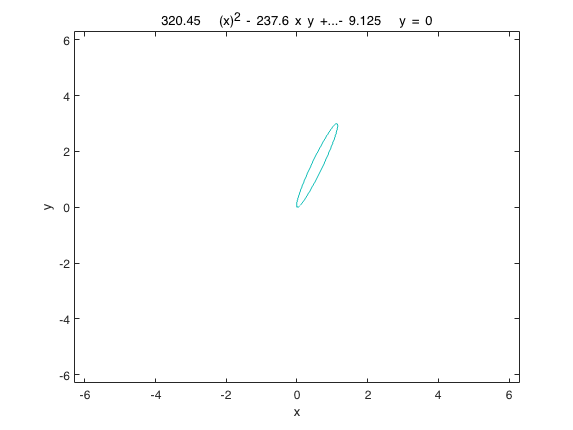

ezplot('320.45 * (x)^2 - 237.6*x*y + 48.2*y^2 -9.125*x - 9.125 * y = 0')

x1 = 0.19784 + h;
x2 = 0.58228;
f = 320.45 * x1^2 - 237.6*x1*x2 + 48.2*x2^2 -9.125*x1 - 9.125 * x2
vpa(f)
diff_ans = diff(f, h)
vpa(diff_ans)
sym(diff_ans=0)

通过迭代计算：


syms x1;
syms x2;
syms x1_val;
syms x2_val;


%% 初始值 x1, x2
x1_val = -0.4;
x2_val = 0.4

x2_val = 0.4000

arr = [x1_val x2_val]

arr =    -0.4000    0.4000



for i = 1 : 100
%% 奇数次迭代
syms h;
x1 = x1_val + h;
x2 = x2_val;

f = 320.45 * (x1)^2 - 237.6*x1*x2 + 48.2*x2^2 -9.125*x1 - 9.125 * x2 == 0 %% 公式

$$f = \frac{6409\,{\left(h-\frac{2}{5}\right)}^{2}}{20}-\frac{20833\,h}{200}+\frac{5716}{125}=0$$

diff_res = diff(f, h)

$$diff\_res = \frac{6409\,h}{10}-\frac{14421}{40}=0$$

h = solve(diff_res)

$$h = \frac{14421}{25636}$$

x1_val = x1_val + h;
arr = [arr; x1_val x2_val]

$$arr = \left(\begin{array}{cc} -\frac{2}{5} & \frac{2}{5}\\ \frac{20833}{128180} & \frac{2}{5} \end{array}\right)$$



%% 偶数次迭代
syms h;
x1 = x1_val;
x2 = x2_val + h;

f = 320.45 * (x1)^2 - 237.6*x1*x2 + 48.2*x2^2 -9.125*x1 - 9.125 * x2 == 0 %% 公式

$$f = \frac{241\,{\left(h+\frac{2}{5}\right)}^{2}}{5}-\frac{61195633\,h}{1281800}-\frac{621156689}{51272000}=0$$

diff_res = diff(f, h)

$$diff\_res = \frac{482\,h}{5}-\frac{470777}{51272}=0$$

h = solve(diff_res)

$$h = \frac{2353885}{24713104}$$

x2_val = x2_val + h;
arr = [arr; x1_val x2_val]

$$arr = \left(\begin{array}{cc} -\frac{2}{5} & \frac{2}{5}\\ \frac{20833}{128180} & \frac{2}{5}\\ \frac{20833}{128180} & \frac{61195633}{123565520} \end{array}\right)$$

end